%% Full scheduling for Multi-tone measurements avoiding DP and SNR-bin overlap
clearvars; close all; clc;

fs = 44100;
blockLength = 4096;
fRatio = 1.3;
f2cand = [500:500:1500 2000:1000:10000].';
%f2cand = (1000:1000:6000).';
dpCoeffs = [
    1  0;    % f1
    0  1;    % f2
    2 -1;    % 2*f1 - f2
];


exclBins = 1; %sidebins which are protected -+ for f1, f1 and 2f1-f2. Typically used for SNR. Should be modified to be vary based on frequency, matching the SNR calculation


%% ---------- Build f1 and f2 pairs ----------
pairs  = [f2cand./fRatio, f2cand];
nPairs = size(pairs,1);

nyq      = fs/2;
binWidth = fs/blockLength;
Nbins    = blockLength/2;

nDPs     = size(dpCoeffs,1);
freqsAll = nan(nPairs,nDPs);

for i = 1:nPairs
    freqs = dpCoeffs(:,1)*pairs(i,1) + dpCoeffs(:,2)*pairs(i,2);
    freqs(freqs<=0 | freqs>=nyq) = NaN;
    freqsAll(i,:) = freqs.';
end

binIdxAll = round(freqsAll/binWidth) + 1;
binIdxAll(isnan(freqsAll)) = NaN;

keepIdx = [1 2 3];   % f1, f2, 2f1-f2


% --- Protected bins per pair (f1, f2, 2f1-f2) + all bins between f1 and f2 ---
protectedBins = cell(nPairs,1);

for i = 1:nPairs
    win = false(1,Nbins);

    % ----- Basic frequency protection (f1, f2, 2f1-f2 ± exclBins) -----
    bins = binIdxAll(i,keepIdx);
    bins = bins(~isnan(bins));

    for b = bins
        lo = max(1,b-exclBins);
        hi = min(Nbins,b+exclBins);
        win(lo:hi) = true;
    end

% ----- NEW: Symmetric ERB protection for f1 and f2 -----
fCenters = [pairs(i,1), pairs(i,2)];
bCenters = binIdxAll(i,1:2);

for k = 1:2
    if ~isnan(bCenters(k))
        fc = fCenters(k);

        % ERB (Glasberg & Moore)
        ERB = 24.7 * (4.37 * fc / 1000 + 1);

        % Symmetric half-bandwidth
        halfBW = ERB / 2;

        % Convert to bins
        halfBins = round(halfBW / binWidth);

        % Apply symmetric window
        lo = max(1, bCenters(k) - halfBins);
        hi = min(Nbins, bCenters(k) + halfBins);

        win(lo:hi) = true;
    end
end

    % ----- Existing full interval protection (f1 → f2) -----
    f1bin = binIdxAll(i,1);
    f2bin = binIdxAll(i,2);

    if ~isnan(f1bin) && ~isnan(f2bin)
        lo = max(1, min(f1bin,f2bin) - exclBins);
        hi = min(Nbins, max(f1bin,f2bin) + exclBins);
        win(lo:hi) = true;
    end

    protectedBins{i} = find(win);
end


% --- All DP bins per pair ---
dpBins = cell(nPairs,1);
for j = 1:nPairs
    bins = binIdxAll(j,:);
    bins = bins(~isnan(bins) & bins>=1 & bins<=Nbins);
    dpBins{j} = unique(bins);
end


% --- Pairwise conflict matrix (Figures out which pairs can be measured at the same time)---
conflict = false(nPairs);
for i = 1:nPairs
    for j = i+1:nPairs
        if any(ismember(dpBins{j},protectedBins{i})) || ...
           any(ismember(dpBins{i},protectedBins{j}))
            conflict(i,j) = true;
            conflict(j,i) = true;
        end
    end
end


% --- Encode conflicts ---
confPairs = find(triu(conflict,1));
nConf     = numel(confPairs);

usesBin = false(nPairs,nConf);
[iList,jList] = ind2sub([nPairs nPairs],confPairs);

for k = 1:nConf
    usesBin(iList(k),k) = true;
    usesBin(jList(k),k) = true;
end

%% =========================================================================
%% Frequency Slot Pairings (read formulas in report)
%% =========================================================================

S      = nPairs;       % Upper bound number of slots (also number of pairs)
numX   = nPairs*S;     % is x_{i,s}
numY   = S;            % is y_{s}
numVar = numX + numY;  % Decision vector combining the decision variables

f      = [zeros(numX,1); ones(numY,1)]; % Minimize Y
intcon = 1:numVar; % Makes sures it is all integers (binary)

%forces all pairs to get assigned exactly once, and only to one slot
Aeq = sparse(nPairs,numVar);
beq = ones(nPairs,1);
for i = 1:nPairs
    Aeq(i,(i-1)*S+(1:S)) = 1;
end


% Enforces no slot can contain two pairs that share any protected/DP bin
nRows_bin = size(usesBin,2)*S;
row_i = []; col_j = []; val_v = [];

r = 0;
for s = 1:S
    for b = 1:size(usesBin,2)
        users = find(usesBin(:,b));
        if isempty(users), continue; end
        r = r+1;
        for k = 1:numel(users)
            row_i(end+1,1) = r;
            col_j(end+1,1) = (users(k)-1)*S + s;
            val_v(end+1,1) = 1;
        end
    end
end
A_bin = sparse(row_i,col_j,val_v,r,numVar);
b_bin = ones(r,1);


% Links constraints (equivalent to x_{i,s} ≤ y_s)
A_link = sparse(nPairs*S,numVar);
r = 0;
for i = 1:nPairs
    for s = 1:S
        r = r+1;
        A_link(r,(i-1)*S+s) = 1;
        A_link(r,numX+s)    = -1;
    end
end
b_link = zeros(nPairs*S,1);


% Passes inequality system to solver
A = [A_bin; A_link];
b = [b_bin; b_link];

lb = zeros(numVar,1);
ub = ones(numVar,1);

opts = optimoptions('intlinprog','Display','off','RelativeGap',1e-3); %Solver options
fprintf('Solving with %d pairs, %d conflicts...\n',nPairs,nConf);

Solving with 12 pairs, 23 conflicts...


[xsol,~,exitflag] = intlinprog(f,intcon,A,b,Aeq,beq,lb,ub,opts); %Solver


%% ---------- Interpret and print solution ----------
if exitflag>0
    xmat = reshape(xsol(1:numX),S,nPairs).';
    usedSlots = find(xsol(numX+1:end)>0.5);

    groups = cell(numel(usedSlots),1);
    for k = 1:numel(usedSlots)
        groups{k} = find(xmat(:,usedSlots(k))>0.5);
    end
    fprintf('optimal found: %d slots used.\n',numel(groups));
else
    error('slot pairing failed');
end

optimal found: 5 slots used.




% --------------Output resulting schedule and details -------------------
fprintf('\nSchedule (slot -> global pair indices -> [f1 f2] Hz -> DPs of interest 2*f1-f2):\n');


Schedule (slot -> global pair indices -> [f1 f2] Hz -> DPs of interest 2*f1-f2):


for s = 1:numel(groups)
    idxs = groups{s}(:).';
    fprintf('Slot %d: %d pairs -> indices: ', s, numel(idxs));
    fprintf('%d ', idxs);
    fprintf('\n');
    disp(array2table([idxs.' pairs(idxs,:) 2*pairs(idxs,1)-pairs(idxs,2)], ...
        'VariableNames',{'globalIdx','f1_Hz','f2_Hz','DP_2f1_minus_f2_Hz'}));
    % Show bins reserved per pair (for debugging)
    fprintf(' Reserved bins per pair (example first 3 DPs):\n');
    for ii = idxs
        used = find(usesBin(ii,:));
        fprintf('  pair %2d: reserved bins count = %d, center DP bins: ', ii, numel(used));
        centers = binIdxAll(ii, ~isnan(binIdxAll(ii,:)));
        fprintf('%d ', centers);
        fprintf('\n');
    end
    fprintf('---\n');
end

Slot 1: 2 pairs -> indices: 

5 11 

    globalIdx    f1_Hz     f2_Hz    DP_2f1_minus_f2_Hz
    _________    ______    _____    __________________

        5        2307.7    3000           1615.4      
       11        6923.1    9000           4846.2      



 Reserved bins per pair (example first 3 DPs):


  pair  5: reserved bins count = 3, center DP bins: 

215 280 151 

  pair 11: reserved bins count = 5, center DP bins: 

644 837 451 

---


Slot 2: 3 pairs -> indices: 

4 7 12 

    globalIdx    f1_Hz     f2_Hz    DP_2f1_minus_f2_Hz
    _________    ______    _____    __________________

        4        1538.5     2000          1076.9      
        7        3846.2     5000          2692.3      
       12        7692.3    10000          5384.6      



 Reserved bins per pair (example first 3 DPs):


  pair  4: reserved bins count = 2, center DP bins: 

144 187 101 

  pair  7: reserved bins count = 6, center DP bins: 

358 465 251 

  pair 12: reserved bins count = 4, center DP bins: 

715 930 501 

---


Slot 3: 2 pairs -> indices: 

1 9 

    globalIdx    f1_Hz     f2_Hz    DP_2f1_minus_f2_Hz
    _________    ______    _____    __________________

        1        384.62     500           269.23      
        9        5384.6    7000           3769.2      



 Reserved bins per pair (example first 3 DPs):


  pair  1: reserved bins count = 1, center DP bins: 

37 47 26 

  pair  9: reserved bins count = 6, center DP bins: 

501 651 351 

---


Slot 4: 3 pairs -> indices: 

2 6 10 

    globalIdx    f1_Hz     f2_Hz    DP_2f1_minus_f2_Hz
    _________    ______    _____    __________________

        2        769.23    1000           538.46      
        6        3076.9    4000           2153.8      
       10        6153.8    8000           4307.7      



 Reserved bins per pair (example first 3 DPs):


  pair  2: reserved bins count = 2, center DP bins: 

72 94 51 

  pair  6: reserved bins count = 4, center DP bins: 

287 373 201 

  pair 10: reserved bins count = 5, center DP bins: 

573 744 401 

---


Slot 5: 2 pairs -> indices: 

3 8 

    globalIdx    f1_Hz     f2_Hz    DP_2f1_minus_f2_Hz
    _________    ______    _____    __________________

        3        1153.8    1500           807.69      
        8        4615.4    6000           3230.8      



 Reserved bins per pair (example first 3 DPs):


  pair  3: reserved bins count = 2, center DP bins: 

108 140 76 

  pair  8: reserved bins count = 6, center DP bins: 

430 558 301 

---



%% ---------- Save schedule for MF_DPOAE_test in file ----------

% Store f2 frequencies
f2aim = pairs(:,2);

% Convert slot groups into matrix format
maxPairsPerSlot = max(cellfun(@numel, groups));
f2Idx = zeros(numel(groups), maxPairsPerSlot);

for s = 1:numel(groups)
    idxs = groups{s};
    f2Idx(s,1:numel(idxs)) = idxs;
end

%Additional outputs (not needed for the script to run)
f1aim = pairs(:,1);
dpAim = 2*f1aim - f2aim;

save('dpFrequenciesExtraLax.mat', ...
    'f1aim', ...
    'f2aim', ...
    'dpAim', ...
    'f2Idx', ...
    'pairs', ...
    'groups', ...
    'blockLength', ...
    'fs', ...
    'fRatio');

fprintf('\nSaved frequency schedule to dpFrequencies.mat\n');


Saved frequency schedule to dpFrequencies.mat


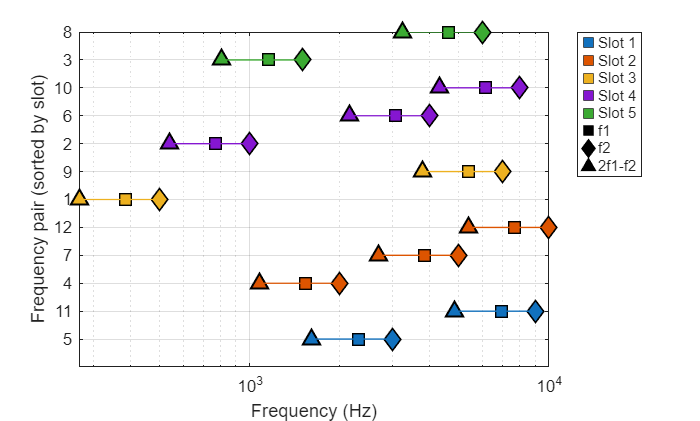


% ---------- Simple visualization (highlights main freqs f1,f2,DP=2f1-f2) ----------
figure('Name','Scheduled groups (frequencies)');
hold on;

% Slot colors
nSlots = max(1,numel(groups));
colors = lines(nSlots);

% Marker shapes for roles
markerMain = {'s','d','^'};         % markers for f1,f2,DP
roleNames = {'f1','f2','2f1-f2'};

% visual params
alphaFactor = 0.45;        % how faded the "other" frequencies are (0..1)
mainMarkerSize = 9;
otherMarkerSize = 6;
mainLineWidth = 1.2;

% Build an ordering that sorts pairs by their assigned slot.
% Pairs in the same slot keep their original index order.
slotOfPair = zeros(size(pairs,1),1);
for s = 1:numel(groups)
    slotOfPair(groups{s}) = s;
end
[~, sortIdx] = sortrows([slotOfPair, (1:size(pairs,1))']); % primary by slot, secondary by original index
sortedPairs = sortIdx(:);

% We'll map original pair index -> y-position (1..nPairs) according to sorting by slot
yPos = nan(size(pairs,1),1);
for y = 1:numel(sortedPairs)
    yPos(sortedPairs(y)) = y;
end

for s = 1:numel(groups)
    idxs = groups{s}(:);
    baseColor = colors(mod(s-1,size(colors,1))+1,:);
    fadedColor = (1-alphaFactor)*baseColor + alphaFactor*[1 1 1]; % fade toward white

    for k = 1:numel(idxs)
        i = idxs(k);
        fRow = freqsAll(i, :);
        valid = ~isnan(fRow);
        fRow = fRow(valid);

        % y position determined by slot-sorted ordering
        y = yPos(i);

        % identify main frequencies for this pair
        f1 = pairs(i,1);
        f2 = pairs(i,2);
        dp = 2*f1 - f2;

        % Plot "other" frequencies (all valid except the three mains) as faded markers
        isMain = abs(fRow - f1) < 1e-9 | abs(fRow - f2) < 1e-9 | abs(fRow - dp) < 1e-9;
        others = fRow(~isMain);
        if ~isempty(others)
            plot(others, y*ones(size(others)), 'o', ...
                'Color', fadedColor, 'MarkerFaceColor', fadedColor, 'MarkerSize', otherMarkerSize);
        end

        % Plot main frequencies with distinct shapes but colored by slot
        plot(f1, y, markerMain{1}, 'MarkerSize', mainMarkerSize, ...
            'MarkerEdgeColor','k', 'MarkerFaceColor', baseColor, 'LineWidth', mainLineWidth);
        plot(f2, y, markerMain{2}, 'MarkerSize', mainMarkerSize, ...
            'MarkerEdgeColor','k', 'MarkerFaceColor', baseColor, 'LineWidth', mainLineWidth);
        plot(dp, y,  markerMain{3}, 'MarkerSize', mainMarkerSize, ...
            'MarkerEdgeColor','k', 'MarkerFaceColor', baseColor, 'LineWidth', mainLineWidth);

        % Connect all frequencies for this pair with a thin line in slot color
        if numel(fRow) > 1
            fRowSorted = sort(fRow);
            plot(fRowSorted, y*ones(size(fRowSorted)), '-', 'Color', baseColor, 'LineWidth', 0.8);
        end
    end
end

set(gca,'xscale','log');
xlabel('Frequency (Hz)');
ylabel('Frequency pair (sorted by slot)'); % indicate y-axis meaning
yticks(1:size(pairs,1));
yticklabels(arrayfun(@num2str, sortedPairs, 'UniformOutput', false)); % show original pair indices in sorted order
grid on; box on;

% Legend:
% - slot color patches
% - role markers
legendHandles = gobjects(0);
legendLabels = {};

% slot color entries (show up to first 10 slots to avoid huge legends)
maxLegendSlots = min(nSlots, 10);
for s = 1:maxLegendSlots
    h = plot(nan, nan, 's', 'MarkerFaceColor', colors(s,:), 'MarkerEdgeColor', 'k', 'MarkerSize', 8);
    legendHandles(end+1) = h; %#ok<SAGROW>
    legendLabels{end+1} = sprintf('Slot %d', s); %#ok<SAGROW>
end

% role markers
for r = 1:numel(markerMain)
    h = plot(nan, nan, markerMain{r}, 'MarkerSize', mainMarkerSize, ...
        'MarkerEdgeColor','k', 'MarkerFaceColor', [0 0 0]); % black face for role legend
    legendHandles(end+1) = h; %#ok<SAGROW>
    legendLabels{end+1} = roleNames{r}; %#ok<SAGROW>
end

legend(legendHandles, legendLabels, 'Location', 'bestoutside');

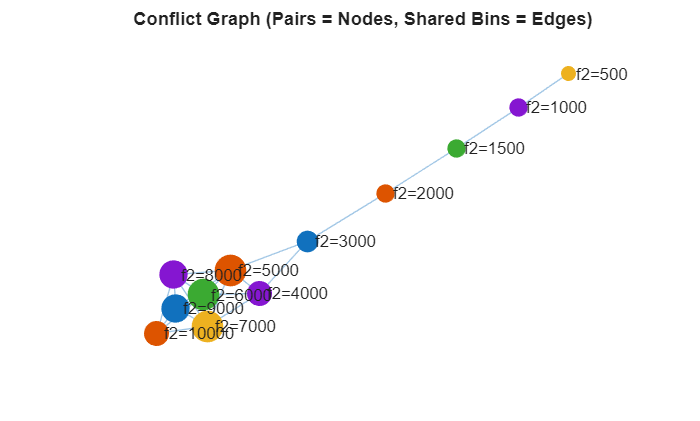



% ---------- Build conflict graph ----------------------------------------

% Nodes = pairs
% Edge between i and j if they share ANY bin
nPairs = size(usesBin,1);


adjMat = false(nPairs);

for b = 1:size(usesBin,2)
    users = find(usesBin(:,b));
    if numel(users) > 1
        % Create all pairwise connections (clique)
        for k1 = 1:numel(users)
            for k2 = k1+1:numel(users)
                i = users(k1);
                j = users(k2);
                adjMat(i,j) = true;
                adjMat(j,i) = true;
            end
        end
    end
end

% Create graph object
G = graph(adjMat);

% ---------- Plot graph ----------
figure('Name','Conflict Graph');
hold on;

% Layout (force-directed gives good structure)
p = plot(G, 'Layout','force');

title('Conflict Graph (Pairs = Nodes, Shared Bins = Edges)');

% ---------- Color nodes by slot assignment ----------
if exist('groups','var')
    nSlots = numel(groups);
    colors = lines(nSlots);

    nodeColors = zeros(nPairs,3); % RGB per node

    for s = 1:nSlots
        idxs = groups{s};
        nodeColors(idxs,:) = repmat(colors(s,:), numel(idxs), 1);
    end

    p.NodeColor = nodeColors;
end


p.MarkerSize = 6 + 2*degree(G);  % bigger nodes = more conflicts
p.LineWidth = 0.5;
p.EdgeAlpha = 0.4;

% Remove axes markings as requested: no x/y ticks or labels
set(gca, 'XTick', [], 'YTick', [], 'XColor', 'none', 'YColor', 'none');

% Label nodes with pair index (but hide axis)
p.NodeLabel = arrayfun(@num2str, 1:nPairs, 'UniformOutput', false);

% Instead of numeric labels, annotate each node with its f2 frequency (optional)
labels = arrayfun(@(i) sprintf('f2=%.0f', pairs(i,2)), 1:nPairs, 'UniformOutput', false);
p.NodeLabel = labels;

axis off; % turn off the axis box

grid off;